# Generate Figures for Proposal

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SDI\MPSFIFforSDI\NewSDIData")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SDI\XTSPIFI\XTSPIFI")
clear variables
%load grids

x=load('xspatvec.mat');
x=x.Expression1;
fx=load('xspatfreq.mat');
fx=fx.Expression1;
y=load('yspatvec.mat');
y=y.Expression1;
fy=load('yspatfreq.mat');
fy=fy.Expression1;
trueimage=load("trueimage.mat");
trueimage=trueimage.Expression1;
mkdir SDI_MPSPIFI_SDIPaper

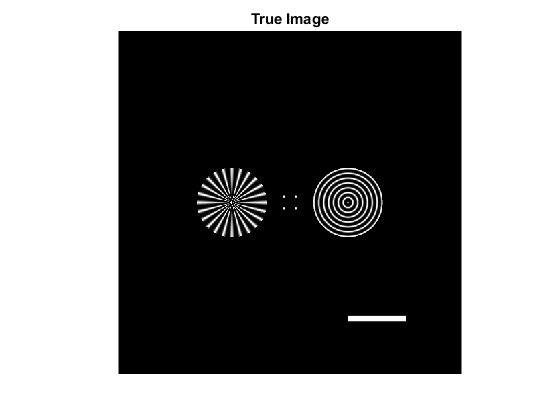

figure; imagesc(x,y,trueimage)
colormap gray
% xlabel('\mum','FontWeight',"bold")
% ylabel('\mum','FontWeight',"bold")
axis square
axis off
title('True Image','FontWeight',"bold")
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/trueimage.svg')

% Noise Free ones
for jj=1:4
    s=load(strcat('imgNF2',num2str(jj),'.mat'));
    imgNF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('imgNF3',num2str(jj),'.mat'));
    imgNF3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
for jj=1:4
    
    imgNF2N(:,:,jj)=Norm(imgNF2(:,:,jj));
end
for jj=1:6
    
    imgNF3N(:,:,jj)=Norm(imgNF3(:,:,jj));
end   

% Noisy ones
for jj=1:4
    s=load(strcat('imgN2',num2str(jj),'.mat'));
    imgN2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('imgN3',num2str(jj),'.mat'));
    imgN3(:,:,jj)=s.Expression1;
end    

for jj=1:4
    s=load(strcat('OTF2',num2str(jj),'.mat'));
    OTF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('OTF3',num2str(jj),'.mat'));
    OTF3(:,:,jj)=s.Expression1;
end    

for ii=1:4
    PSF2(:,:,ii)=abs(ifftshift(ifft2(OTF2(:,:,ii))));
end
for ii=1:6
    PSF3(:,:,ii)=abs(ifftshift(ifft2(OTF3(:,:,ii))));
end
% Normalized Versions
for ii=1:4
    PSF2N(:,:,ii)=Norm(PSF2(:,:,ii));
end
for ii=1:6
    PSF3N(:,:,ii)=Norm(PSF3(:,:,ii));
end

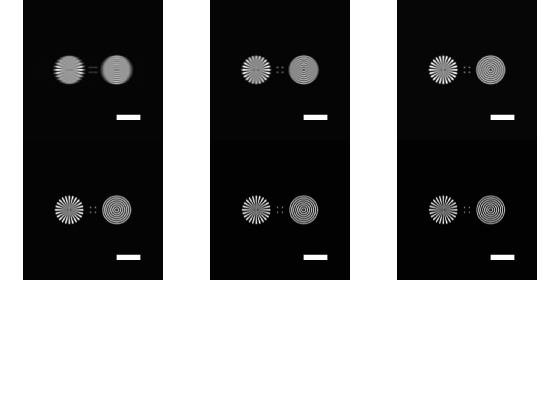

figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap gray
nexttile
imagesc(x,x,imgNF3(:,:,1))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNF3(:,:,2))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNF3(:,:,3))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNF3(:,:,4))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNF3(:,:,5))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNF3(:,:,6))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
saveas(gcf,'SDI_MPSPIFI_SDIPaper/NoiseFree3pSPIFIImages.svg')

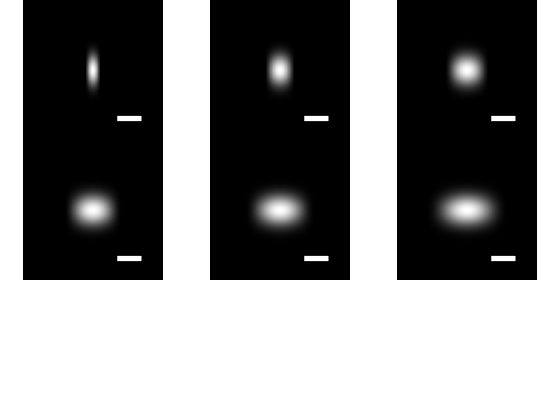

figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap gray
nexttile
imagesc(fx,fx,OTF3(:,:,1))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTF3(:,:,2))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTF3(:,:,3))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTF3(:,:,4))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTF3(:,:,5))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTF3(:,:,6))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pSPIFIOTFs.svg')

for jj=1:6
    s=load(strcat('imgNFXT3',num2str(jj),'.mat'));
    imgNFXT3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
% for jj=1:4
%     
%     imgN2N(:,:,jj)=Norm(imgN2(:,:,jj));
% end
for jj=1:6
    
    imgNFXT3N(:,:,jj)=Norm(imgNFXT3(:,:,jj));
end 

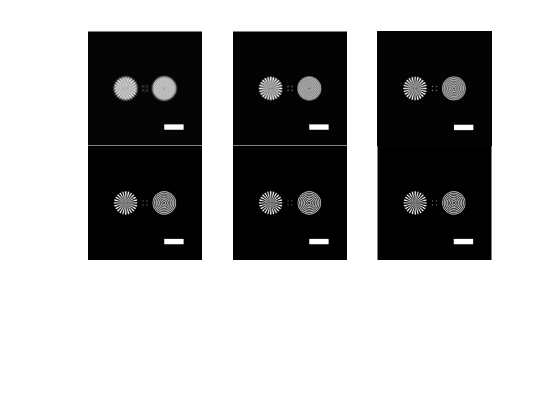

figure;
t=tiledlayout(3,3);
colormap gray
nexttile
imagesc(x,x,imgNFXT3(:,:,1))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNFXT3(:,:,2))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNFXT3(:,:,3))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNFXT3(:,:,4))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNFXT3(:,:,5))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imgNFXT3(:,:,6))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
t.TileSpacing = 'none';
saveas(gcf,'SDI_MPSPIFI_SDIPaper/NoiseFree3pXTSPIFIImages.svg')

for jj=1:6
    s=load(strcat('OTFXT3',num2str(jj),'.mat'));
    OTFXT3(:,:,jj)=s.Expression1;
end  

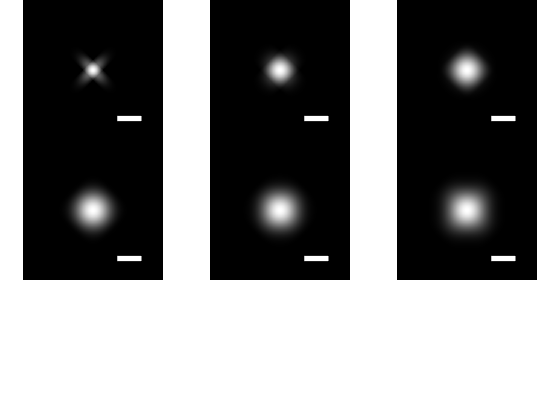

figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap gray
nexttile
imagesc(fx,fx,OTFXT3(:,:,1))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTFXT3(:,:,2))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTFXT3(:,:,3))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTFXT3(:,:,4))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTFXT3(:,:,5))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(fx,fx,OTFXT3(:,:,6))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
axis square
axis off
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pXTSPIFIOTFs.svg')

recimgXT3p=load('imgNXT3ReconUnCorrNoise.mat');

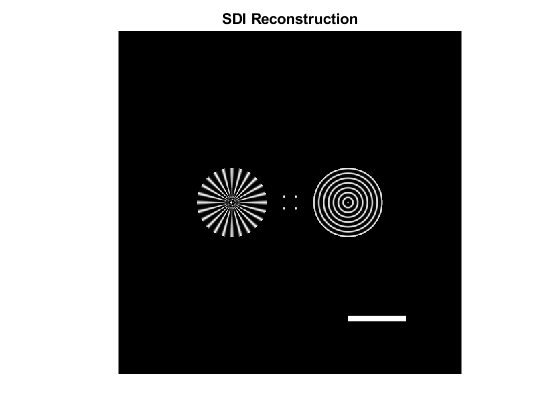

figure;
imagesc(x,x,recimgXT3p.recMPIMNXT3(:,:,end))
colormap gray
axis square
axis off
title('SDI Reconstruction','FontWeight',"bold")
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrec3pXTSPIFINF.svg')

recimg3p=load('imgNF3Recon.mat');

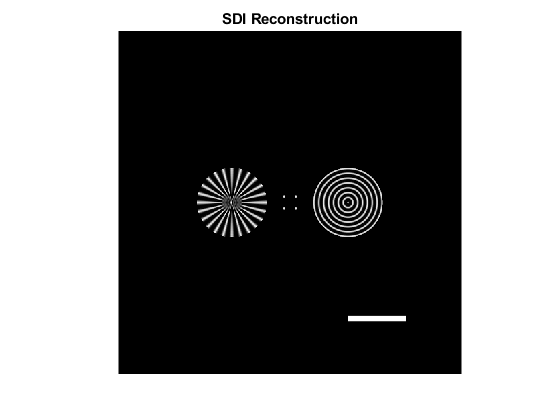

figure;
imagesc(x,x,recimg3p.recMPIMNF3(:,:,end))
colormap gray
axis square
axis off
title('SDI Reconstruction','FontWeight',"bold")
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrec3pSPIFINF.svg')

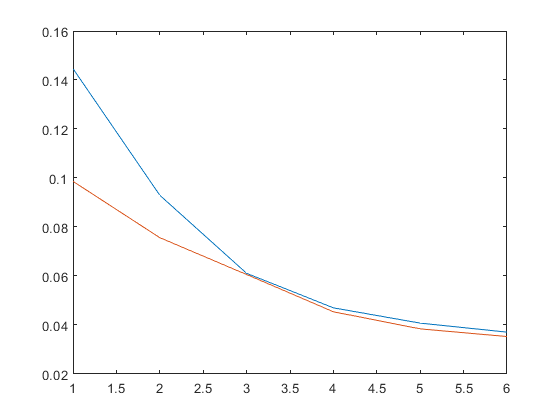

% Error in Each Harmonic image (Adding Noise to Randy's)
% for ii=1:size(imNGXT3v2,3)
%     errorharmsGNXT3(ii)=immse(Norm(imNGXT3v2(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
%     
% end
% for ii=1:size(imNG3v2,3)
%     errorharmsimNG3v2(ii)=immse(Norm(imNG3v2(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
%     
% end

for ii=1:size(imgNFXT3,3)
    errorharmsimgNFXT3(ii)=immse(Norm(imgNFXT3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imgNF3,3)
    errorharmsimimgNF3(ii)=immse(Norm(imgNF3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imgNFXT3,3)
    errorharmsimgNFXT3sm(ii)=ssim(Norm(imgNFXT3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imgNF3,3)
    errorharmsimimgNF3sm(ii)=ssim(Norm(imgNF3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
% for ii=1:size(imgN2new1N,3)
%     errorharmsRGN2(ii)=immse(Norm(imgN2new1N(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
%     
% end
% figure; plot(errorharmsGNXT3)
% hold on
% plot(errorharmsimNG3v2)

figure; plot(errorharmsimgNFXT3)
hold on
plot(errorharmsimimgNF3)

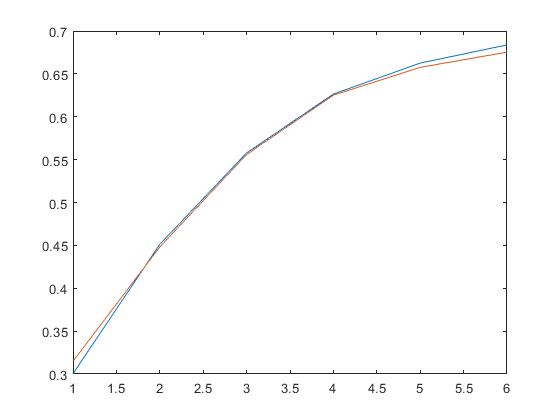

figure; plot(errorharmsimgNFXT3sm)
hold on
plot(errorharmsimimgNF3sm)

% figure; plot(errorharmsRGN2)
% % Corresponding error in reconstructions
% eval
% eval2

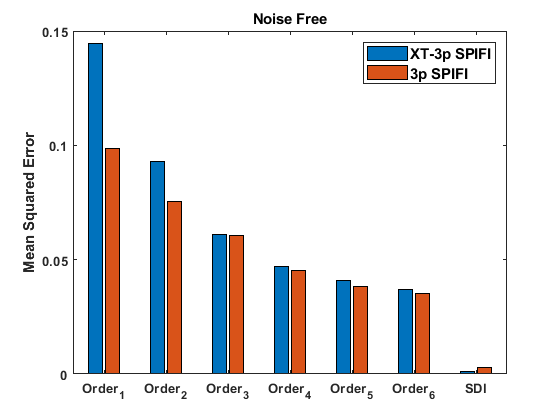

Xn = categorical({'Order_1','Order_2','Order_3','Order_4','Order_5','Order_6','SDI'});

Yn = [errorharmsimgNFXT3(1) errorharmsimimgNF3(1); errorharmsimgNFXT3(2) errorharmsimimgNF3(2); errorharmsimgNFXT3(3) errorharmsimimgNF3(3); errorharmsimgNFXT3(4) errorharmsimimgNF3(4); errorharmsimgNFXT3(5) errorharmsimimgNF3(5); errorharmsimgNFXT3(6) errorharmsimimgNF3(6); immse(Norm(recimgXT3p.recMPIMNXT3(200:311,112:400,end)),Norm(trueimage(200:311,112:400))) immse(Norm(recimg3p.recMPIMNF3(200:311,112:400,end)),Norm(trueimage(200:311,112:400)));];
figure;
bar(Xn,Yn)
ylabel('Mean Squared Error','FontWeight',"bold")
title('Noise Free','FontWeight',"bold")
legend({'XT-3p SPIFI','3p SPIFI'},'FontWeight',"bold",'FontSize',11)
set(gca,'FontWeight',"bold")
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrecNF3p_MSEbargraph_SPIFIvsXT.svg')

% Take 1d fft of object along x direction
f_x_Object=(fftshift(fft(trueimage,[],2),2));
% Take 1d fft of psfs along y direction
for ii=1:4
    f_y_PSF2(:,:,ii)=fftshift(fft(PSF2(:,:,ii),[],1),1);
end

for ii=1:6
    f_y_PSF3(:,:,ii)=fftshift(fft(PSF3(:,:,ii),[],1),1);
end

for jj=1:4
for ii=1:512
    OTF2x(ii,:,jj)=OTF2(end/2,:,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3x(ii,:,jj)=OTF3(end/2,:,jj);
end
end

for jj=1:4
for ii=1:512
    OTF2yy(:,ii,jj)=OTF2(:,end/2,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3yy(:,ii,jj)=OTF3(:,ii,jj);
end
end

for ii=1:4
    sig2Gx(:,:,ii)=OTF2x(:,:,ii).*f_x_Object;
end
for ii=1:4
    fftim2Gx(:,:,ii)=fftshift(abs(ifftshift(ifft(sig2Gx(:,:,ii),[],2),2)),2);
end

for ii=1:4
    sig2Gv2(:,:,ii)=((((OTF2(:,:,ii).*fftshift(fft2(fftim2Gx(:,:,ii)))))));
end

for ii=1:4
    sig2Gv3(:,:,ii)=ifft(((((OTF2yy(:,:,ii).*fftshift(fft(sig2Gx(:,:,ii),[],1),1))))),[],1);
end

for ii=1:4
    fftim2Gv2(:,:,ii)=(abs((ifft2(OTF2(:,:,ii).*fftshift(fft2(fftim2Gx(:,:,ii)))))));
end
for ii=1:4
    fftim2Gv3(:,:,ii)=conv_fft2(PSF2(:,:,ii),fftim2Gx(:,:,ii),'same');
end

for ii=1:6
    sig3Gx(:,:,ii)=OTF3x(:,:,ii).*f_x_Object;
end
for ii=1:6
    fftim3Gx(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gx(:,:,ii),[],2),2)),2);
end

for ii=1:6
    sig3Gv2(:,:,ii)=((((OTF3(:,:,ii).*fftshift(fft2(fftim3Gx(:,:,ii)))))));
end

for ii=1:6
    sig3Gv3(:,:,ii)=ifft(((((OTF3yy(:,:,ii).*fftshift(fft(sig3Gx(:,:,ii),[],1),1))))),[],1);
end

for ii=1:6
    fftim3Gv2(:,:,ii)=(abs((ifft2(OTF3(:,:,ii).*fftshift(fft2(fftim3Gx(:,:,ii)))))));
end
for ii=1:6
    fftim3Gv3(:,:,ii)=conv_fft2(PSF3(:,:,ii),fftim3Gx(:,:,ii),'same');
end

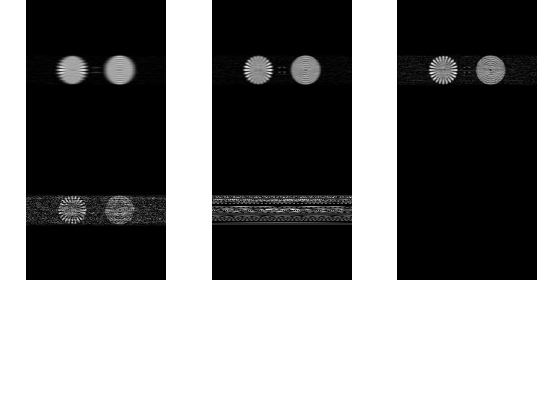

o1=max(max(mean(real(sum(sig3Gv3,3)+9),2)));
%o1=max(max(abs(sig3Gv3(:,:,1))));
maxphtcnt=255000;
figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap gray
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,1),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,2),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,3),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,4),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,5),o1,maxphtcnt),[],2),2)),2))
axis square
axis off
nexttile
imagesc(fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,6),o1,maxphtcnt),[],2),2)),2))
axis square
axis off

%o1=max(max(abs(sig2Gv3(:,:,1))));
o1=max(max(mean(real(sum(sig3Gv3,3)+9),2)));
maxphtcnt=255000;
for ii=1:4
    imNG2(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end
%o1=max(max(abs(sig3Gv3(:,:,1))));
%maxphtcnt=2550;
for ii=1:6
    imNG3(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

imNG3T=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sum(sig3Gv3,3),o1,maxphtcnt),[],2),2)),2);

Noise Free

for ii=1:4
    imNFG2(:,:,ii)=fftshift(abs(ifftshift(ifft(sig2Gv3(:,:,ii),[],2),2)),2);
end
% o1=max(max(abs(sig3Gv3(:,:,1))));
% maxphtcnt=2550;
for ii=1:6
    imNFG3(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gv3(:,:,ii),[],2),2)),2);
end
imNFG3T=fftshift(abs(ifftshift(ifft(sum(sig3Gv3,3),[],2),2)),2);

Extract Noise

%o1=max(max(abs(sig2Gv3(:,:,1))));
o1=max(max(mean(real(sum(sig2Gv3,3)+9),2)));
for ii=1:4
    G2N(:,:,ii)=imNG2(:,:,ii)-imNFG2(:,:,ii)*maxphtcnt/o1;
end
%o1=max(max(abs(sig3Gv3(:,:,1))));
o1=max(max(mean(real(sum(sig3Gv3,3)+9),2)));
for ii=1:6
    G3N(:,:,ii)=imNG3(:,:,ii)-imNFG3(:,:,ii)*maxphtcnt/o1;
end
G3NT=imNG3T-imNFG3T*maxphtcnt/o1;

Add noise to noise free from Randy

for ii=1:6
    imNG3v2(:,:,ii)=Norm(imgNF3(:,:,ii))*max(max(imNFG3(:,:,ii)))*maxphtcnt/o1+G3N(:,:,ii);
end
imNG3v2(:,:,5)=Norm(imgN3(:,:,5))*.0125;%abs(Norm(imgNF3(:,:,5))*max(max(imNFG3(:,:,5)))*maxphtcnt/o1+G3N(:,:,4));
imNG3v2(:,:,6)=Norm(imgN3(:,:,6))*.0125;%abs(Norm(imgNF3(:,:,6))*max(max(imNFG3(:,:,6)))*maxphtcnt/o1+G3N(:,:,4));

for ii=1:6
    imNG3v3(:,:,ii)=Norm(conv_fft2(PSF3(:,:,ii),trueimage,'same'))*max(max(imNFG3(:,:,ii)))*maxphtcnt/o1+G3N(:,:,ii);
end
for ii=1:6
    imNG3v3NF(:,:,ii)=Norm(conv_fft2(PSF3(:,:,ii),trueimage,'same'))*max(max(imNFG3(:,:,ii)))*maxphtcnt/o1;
end
imNG3v3NF(:,:,5)=zeros(size(trueimage));
imNG3v3NF(:,:,6)=zeros(size(trueimage));
imNG3v3(:,:,5)=Norm(imgN3(:,:,5))*.0125;%abs(Norm(imgNF3(:,:,5))*max(max(imNFG3(:,:,5)))*maxphtcnt/o1+G3N(:,:,4));
imNG3v3(:,:,6)=Norm(imgN3(:,:,6))*.0125;%abs(Norm(imgNF3(:,:,6))*max(max(imNFG3(:,:,6)))*maxphtcnt/o1+G3N(:,:,4));
G3N(:,:,5)=Norm(imgN3(:,:,5))*.0125;
G3N(:,:,6)=Norm(imgN3(:,:,6))*.0125;

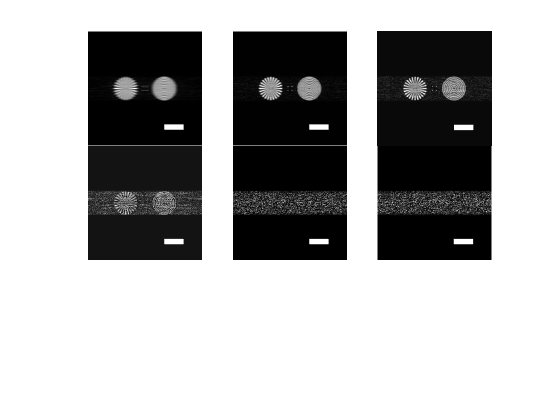

figure;
t=tiledlayout(3,3);
colormap gray
nexttile
imagesc(x,x,imNG3v3(:,:,1))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNG3v3(:,:,2))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNG3v3(:,:,3))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNG3v3(:,:,4))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNG3v3(:,:,5))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNG3v3(:,:,6))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
t.TileSpacing = 'none';
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pSPIFIImageswNoise.svg')

for ii=1:6
    imNG3v3N(:,:,ii)=Norm(imNG3v3(:,:,ii));
    imNG3v3NFN(:,:,ii)=Norm(imNG3v3NF(:,:,ii));
    imgN3N(:,:,ii)=Norm(imgN3(:,:,ii));
    G3Nn(:,:,ii)=Norm(G3N(:,:,ii));
end
NFreshaped=reshape(imNG3v3NFN,[s(1) s(1)*s(3)]);

Index exceeds the number of array elements (1).

NFreshaped(isnan(NFreshaped))=0;
ReshapedNoise=reshape(imNG3v3N,[s(1) s(1)*s(3)])-NFreshaped;

s=size(PSF3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
%delta=Norm(abs(ifftshift(ifft2(ones(size(trueimage))+1i*ones(size(trueimage))))));
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
reshapednoise=reshape(G3N,[s(1) s(1)*s(3)]);
Imdata=reshape(imNG3v3N,[s(1) s(1)*s(3)]);
%ImdataNF=conv_fft2(param2,Norm(trueimage));
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 142.564017 seconds.


clear recMPIMN3 errorrecrecMPIMN3
recMPIMN3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm);
for ii=1:size(recMPIMN3,3)
    errorrecrecMPIMN3(ii)=immse(Norm(trueimage(200:311,112:400)),Norm(recMPIMN3(200:311,112:400,ii)));
end

[eval locm]=min(errorrecrecMPIMN3);
eval

eval = 0.0263

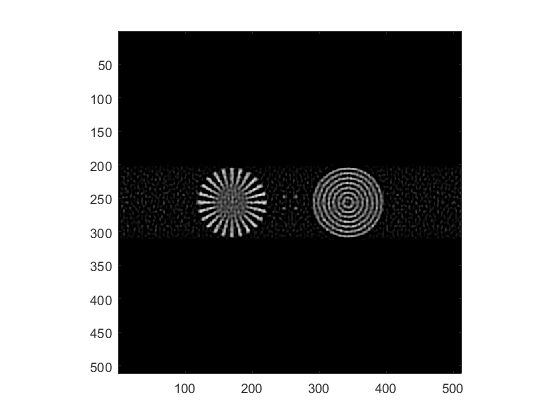

figure; imagesc(recMPIMN3(:,:,locm))
axis square
colormap gray

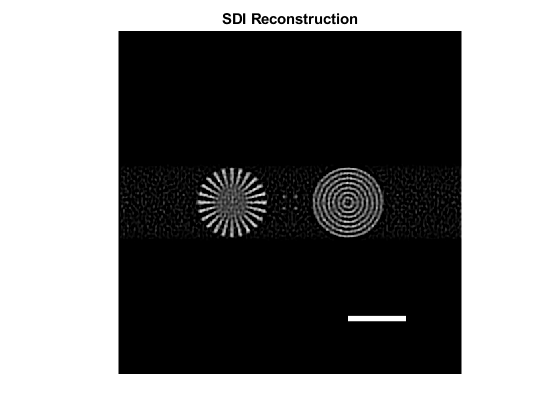

figure;
imagesc(x,x,recMPIMN3(:,:,locm))
colormap gray
axis square
axis off
title('SDI Reconstruction','FontWeight',"bold")
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrec3pSPIFIwNoise.svg')

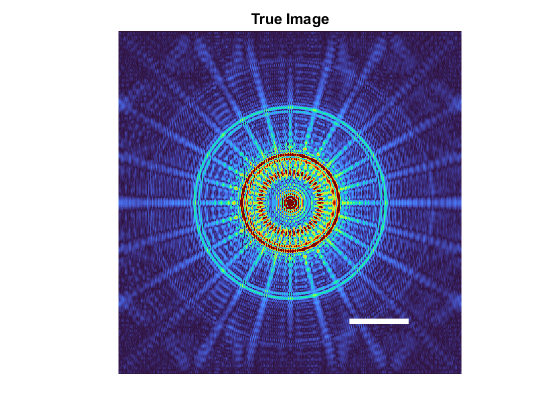

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(trueimage)))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
colormap Turbo
title('True Image','FontWeight',"bold")
saveas(gcf,'SDI_MPSPIFI_SDIPaper/trueimageSpatFreq.svg')

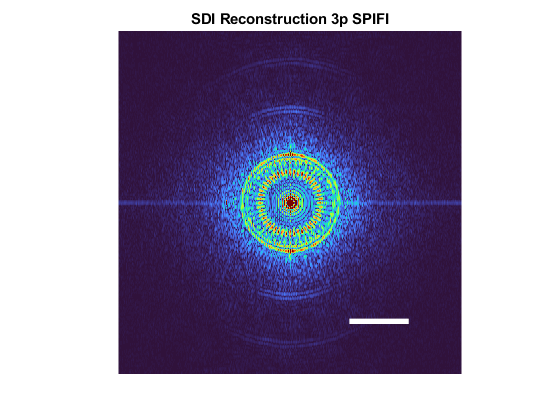

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(recMPIMN3(:,:,locm))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
colormap Turbo
title('SDI Reconstruction 3p SPIFI','FontWeight',"bold")
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDI3pSPIFIwithNoiseSpatFreq.svg')

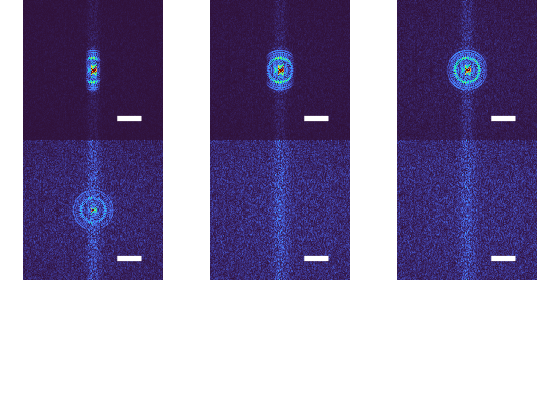

figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap Turbo
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3(:,:,1))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3(:,:,2))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3(:,:,3))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3(:,:,4))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3(:,:,5))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgN3(:,:,6))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pSPIFINspat_freq.svg')

Ntheta=20;
trueimFave=GabeRadialAvg(abs(fftshift(fft2(trueimage))),Ntheta);
FaveRGN3=GabeRadialAvg(abs(fftshift(fft2(recMPIMN3(:,:,locm)))),Ntheta);
%FaveRGN2=GabeRadialAvg(abs(fftshift(fft2(RGN2))),Ntheta);
% FaveGN3=GabeRadialAvg(abs(fftshift(fft2(GN3))),Ntheta);
% FaveGN2=GabeRadialAvg(abs(fftshift(fft2(GN2))),Ntheta);
% FaveNF3=GabeRadialAvg(abs(fftshift(fft2(NF3))),Ntheta);
% FaveNF2=GabeRadialAvg(abs(fftshift(fft2(NF2))),Ntheta);

FaveGN3H1=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,1)))),Ntheta);
FaveGN3H2=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,2)))),Ntheta);
FaveGN3H3=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,3)))),Ntheta);
FaveGN3H4=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,4)))),Ntheta);
FaveGN3H5=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,5)))),Ntheta);
FaveGN3H6=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,6)))),Ntheta);


% FaveGN2H1=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,1)))),Ntheta);
% FaveGN2H2=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,2)))),Ntheta);
% FaveGN2H3=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,3)))),Ntheta);
% FaveGN2H4=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,4)))),Ntheta);

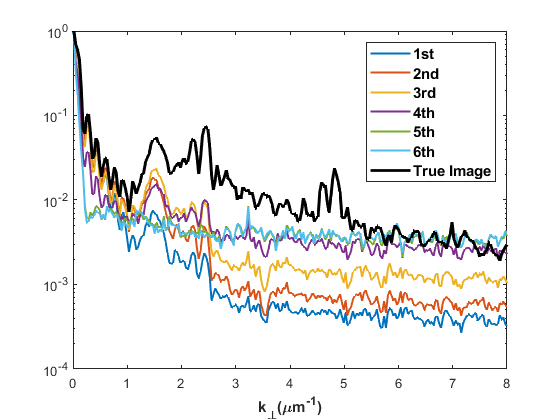

figure; semilogy(fx,(Norm(FaveGN3H1)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('k_{\perp}(\mum^{-1})','FontWeight','Bold')
legend({'1st','2nd','3rd','4th','5th','6th','True Image'},'FontWeight','Bold','FontSize',11)
% semilogy((Norm(FaveN3H5(end/2:end))))
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pSPIFIN_radialave_spat_freq.svg')

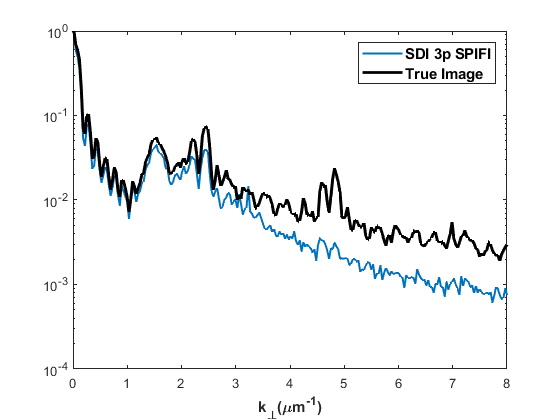

figure; semilogy(fx,(Norm(FaveRGN3)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


% semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('k_{\perp}(\mum^{-1})','FontWeight','Bold')
legend({'SDI 3p SPIFI','True Image'},'FontWeight','Bold','FontSize',11)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrec3pSPIFIN_radialave_spat_freq.svg')

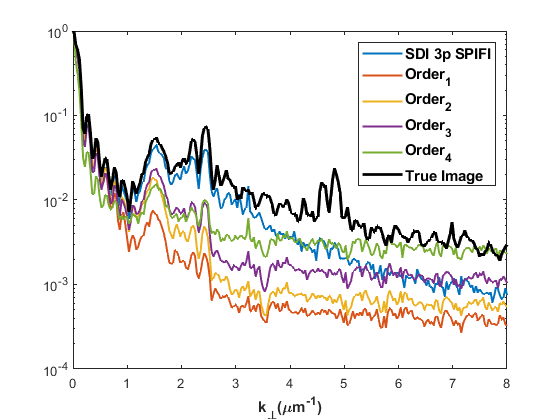

figure; semilogy(fx,(Norm(FaveRGN3)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


semilogy(fx,(Norm(FaveGN3H1)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('k_{\perp}(\mum^{-1})','FontWeight','Bold')
legend({'SDI 3p SPIFI','Order_1','Order_2','Order_3','Order_4','True Image'},'FontWeight','Bold','FontSize',11)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrec3pSPIFIN_radialave_spat_freqfullv3.svg')

# Now for XT

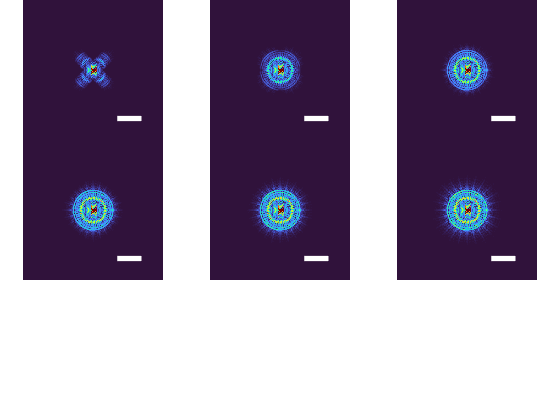

figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap Turbo
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgNFXT3(:,:,1))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgNFXT3(:,:,2))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgNFXT3(:,:,3))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgNFXT3(:,:,4))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgNFXT3(:,:,5))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imgNFXT3(:,:,6))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pSPIFINspat_freq.svg')

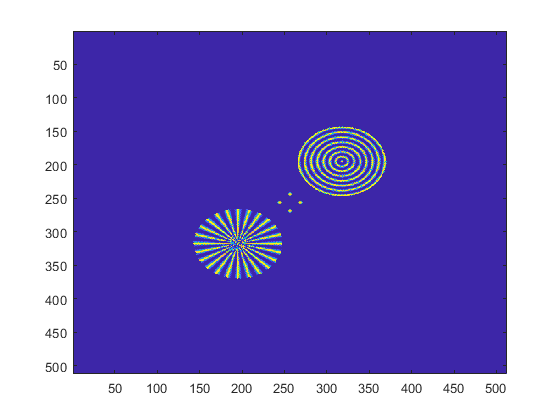

trueimage45=imrotate(trueimage,45,'crop');
trueimagem45=imrotate(trueimage,-45,'crop');
f_x_Object45=(fftshift(fft(trueimage45,[],2),2));
f_x_Objectm45=(fftshift(fft(trueimagem45,[],2),2));
figure; imagesc(trueimage45)

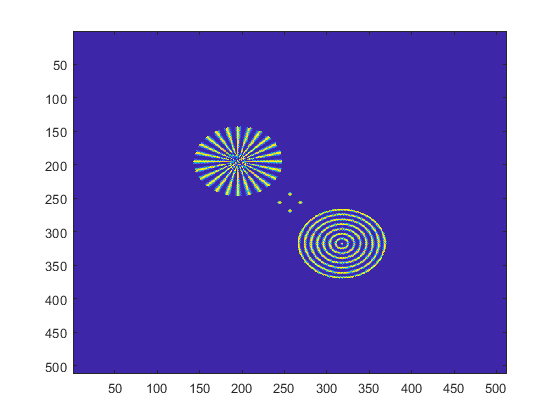

figure; imagesc(trueimagem45)

OTFs in x and y

for jj=1:4
for ii=1:512
    OTF2x(ii,:,jj)=OTF2(end/2,:,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3x(ii,:,jj)=OTF3(end/2,:,jj);
end
end

for jj=1:4
for ii=1:512
    OTF2yy(:,ii,jj)=OTF2(:,end/2,jj);
end
end

for jj=1:6
for ii=1:512
    OTF3yy(:,ii,jj)=OTF3(:,ii,jj);
end
end

Generate signals for each rotation

for ii=1:4
    sig2Gx45(:,:,ii)=OTF2x(:,:,ii).*f_x_Object45;
end
for ii=1:4
    sig2Gv345(:,:,ii)=ifft(((((OTF2yy(:,:,ii).*fftshift(fft(sig2Gx45(:,:,ii),[],1),1))))),[],1);
end
for ii=1:6
    sig3Gx45(:,:,ii)=OTF3x(:,:,ii).*f_x_Object45;
end
for ii=1:6
    sig3Gv345(:,:,ii)=ifft(((((OTF3yy(:,:,ii).*fftshift(fft(sig3Gx45(:,:,ii),[],1),1))))),[],1);
end

for ii=1:4
    sig2Gxm45(:,:,ii)=OTF2x(:,:,ii).*f_x_Objectm45;
end
for ii=1:4
    sig2Gv3m45(:,:,ii)=ifft(((((OTF2yy(:,:,ii).*fftshift(fft(sig2Gxm45(:,:,ii),[],1),1))))),[],1);
end
for ii=1:6
    sig3Gxm45(:,:,ii)=OTF3x(:,:,ii).*f_x_Objectm45;
end
for ii=1:6
    sig3Gv3m45(:,:,ii)=ifft(((((OTF3yy(:,:,ii).*fftshift(fft(sig3Gxm45(:,:,ii),[],1),1))))),[],1);
end

% o1=max(max(abs(sig2Gv345(:,:,1))));
% maxphtcnt=255000;
% for ii=1:4
%     imNGXT245(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv345(:,:,ii),o1,maxphtcnt),[],2),2)),2);
% end
o1=9;%max(max(abs(sig3Gv345(:,:,1))));
maxphtcnt=255000*2;
for ii=1:6
    imNGXT345(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv345(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

% o1=max(max(abs(sig2Gv3m45(:,:,1))));
% maxphtcnt=255000;
% for ii=1:4
%     imNGXT2m45(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3m45(:,:,ii),o1,maxphtcnt),[],2),2)),2);
% end
o1=9;%max(max(abs(sig3Gv3m45(:,:,1))));
maxphtcnt=255000*2;
for ii=1:6
    imNGXT3m45(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig3Gv3m45(:,:,ii),o1,maxphtcnt),[],2),2)),2);
end

for ii=1:6
    imNGXT345NF(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gv345(:,:,ii),[],2),2)),2);
end

% o1=max(max(abs(sig2Gv3m45(:,:,1))));
% maxphtcnt=255000;
% for ii=1:4
%     imNGXT2m45(:,:,ii)=fftshift(abs(ifftshift(ifft(MPSpifiPoissNoise(sig2Gv3m45(:,:,ii),o1,maxphtcnt),[],2),2)),2);
% end

for ii=1:6
    imNGXT3m45NF(:,:,ii)=fftshift(abs(ifftshift(ifft(sig3Gv3m45(:,:,ii),[],2),2)),2);
end

Rotate back to center and add

% for ii=1:4
%     imgNGXT2(:,:,ii)=(imrotate(imNGXT2m45(:,:,ii),45,'crop')+imrotate(imNGXT245(:,:,ii),-45,'crop'))/2;
% end
for ii=1:6
    imgNGXT3(:,:,ii)=(imrotate(imNGXT3m45(:,:,ii),45,'crop')+imrotate(imNGXT345(:,:,ii),-45,'crop'))/2;
end
for ii=1:6
    imgNGXT3NF(:,:,ii)=((imrotate(imNGXT3m45NF(:,:,ii),45,'crop')+imrotate(imNGXT345NF(:,:,ii),-45,'crop'))/2)*maxphtcnt/9;
end

figure;
t=tiledlayout(3,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


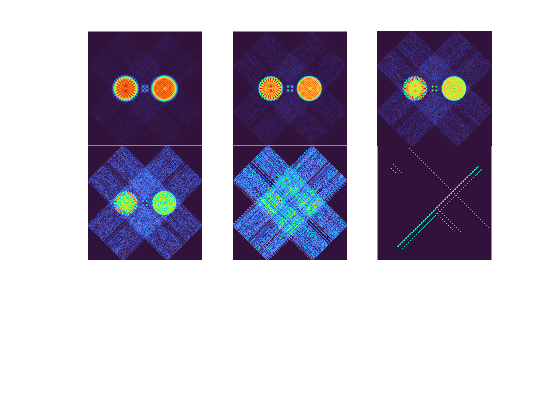

colormap Turbo
nexttile
imagesc(imgNGXT3(:,:,1))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,2))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,3))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,4))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,5))
axis square
axis off
nexttile
imagesc(imgNGXT3(:,:,6))
axis square
axis off
t.TileSpacing = 'none';

for ii=1:6
    GXTNoise(:,:,ii)=imgNGXT3(:,:,ii)-imgNGXT3NF(:,:,ii);
end

for ii=1:6
    PSFXT3(:,:,ii)=abs(ifftshift(ifft2(OTFXT3(:,:,ii))));
end
for ii=1:6
    PSFXT3N(:,:,ii)=Norm(PSFXT3(:,:,ii));
end

for ii=1:6
    imNGXT3v3(:,:,ii)=Norm(conv_fft2(PSFXT3(:,:,ii),trueimage,'same'))*max(max(imgNGXT3NF(:,:,ii)))+GXTNoise(:,:,ii);
end
for ii=1:6
    imNGXT3v3NF(:,:,ii)=Norm(conv_fft2(PSFXT3(:,:,ii),trueimage,'same'))*max(max(imgNGXT3NF(:,:,ii)));
end
imNGXT3v3(:,:,5)=abs(imNGXT3v3(:,:,4)-imNGXT3v3NF(:,:,4))+imrotate(abs(imNGXT3v3(:,:,4)-imNGXT3v3NF(:,:,4)),90,'crop')/2;
imNGXT3v3(:,:,6)=abs(imNGXT3v3(:,:,4)-imNGXT3v3NF(:,:,4))+imrotate(abs(imNGXT3v3(:,:,4)-imNGXT3v3NF(:,:,4)),-90,'crop')/2;

for ii=1:6
    tritry=imNGXT3v3(:,:,ii);
tritry(1:149,364:512)=tritry(1:149,364:512)+tritry(363:511,1:149);
tritry(364:512,1:149)=tritry(1:149,363:511);
tritry(1:149,1:149)=tritry(1:149,1:149)+circshift(tritry(363:511,363:511),-1);%circshift(tritry(363:509,363:509),-1)
tritry(149,1:149)=imNGXT3v3(149,1:149,ii);
tritry(363:511,363:511)=tritry(1:149,1:149);
imNGXT3v3c(:,:,ii)=tritry;
end

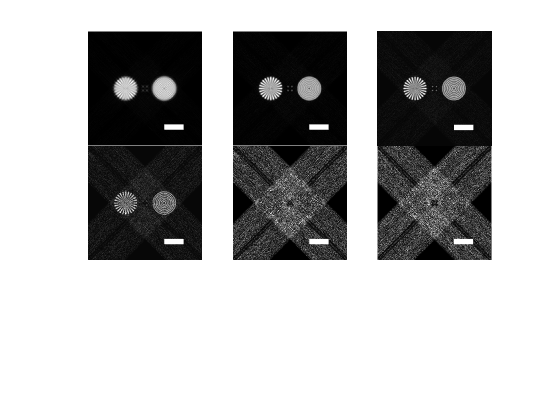

figure;
t=tiledlayout(3,3);
colormap gray
nexttile
imagesc(x,x,imNGXT3v3c(:,:,1))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNGXT3v3c(:,:,2))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNGXT3v3c(:,:,3))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNGXT3v3c(:,:,4))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNGXT3v3c(:,:,5))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
nexttile
imagesc(x,x,imNGXT3v3c(:,:,6))
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
axis square
axis off
t.TileSpacing = 'none';
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pXTSPIFIImageswNoise.svg')

for ii=1:6
    imNGXT3v3cN(:,:,ii)=Norm(imNGXT3v3c(:,:,ii));
%     imNG3v3NFN(:,:,ii)=Norm(imNG3v3NF(:,:,ii));
%     imgN3N(:,:,ii)=Norm(imgN3(:,:,ii));
%     G3Nn(:,:,ii)=Norm(G3N(:,:,ii));
end
% NFreshaped=reshape(imNG3v3NFN,[s(1) s(1)*s(3)]);
% NFreshaped(isnan(NFreshaped))=0;
% ReshapedNoise=reshape(imNG3v3N,[s(1) s(1)*s(3)])-NFreshaped;

imNGXT3v3cNv2=imNGXT3v3cN;
imNGXT3v3cNv2(:,:,5)=imNGXT3v3cNv2(:,:,5)*.18;
imNGXT3v3cNv2(:,:,6)=imNGXT3v3cNv2(:,:,6)*.18;

s=size(PSFXT3N(:,:,1:4));
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
%delta=Norm(abs(ifftshift(ifft2(ones(size(trueimage))+1i*ones(size(trueimage))))));
param2=reshape(PSFXT3N(:,:,1:4),[s(1) s(1)*s(3)]);%OBBB2;
%reshapednoise=reshape(G3N,[s(1) s(1)*s(3)]);
Imdata=reshape(imNGXT3v3cN(:,:,1:4),[s(1) s(1)*s(3)]);
%ImdataNF=conv_fft2(param2,Norm(trueimage));
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 92.435504 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm);
for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage(200:311,112:400)),Norm(recMPIMN3XT(200:311,112:400,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
evalXT

evalXT = 0.0253

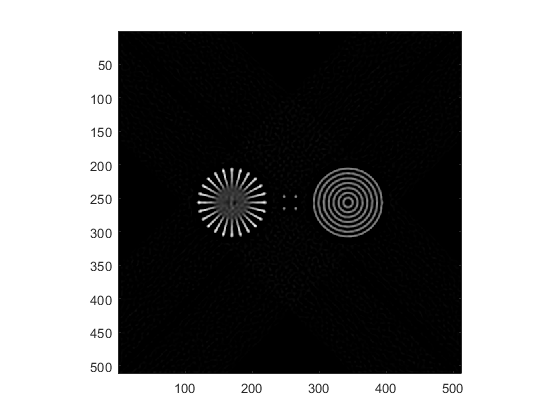

figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray

s=size(PSFXT3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
%delta=Norm(abs(ifftshift(ifft2(ones(size(trueimage))+1i*ones(size(trueimage))))));
param2=reshape(PSFXT3N,[s(1) s(1)*s(3)]);%OBBB2;
%reshapednoise=reshape(G3N,[s(1) s(1)*s(3)]);
Imdata=reshape(imNGXT3v3cNv2,[s(1) s(1)*s(3)]);
%ImdataNF=conv_fft2(param2,Norm(trueimage));
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=100;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 148.289070 seconds.


clear recMPIMN3XTv2 errorrecrecMPIMN3XTv2
recMPIMN3XTv2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm);
for ii=1:size(recMPIMN3XTv2,3)
    errorrecrecMPIMN3XTv2(ii)=immse(Norm(trueimage(200:311,112:400)),Norm(recMPIMN3XTv2(200:311,112:400,ii)));
end

[evalXTv2 locmXTv2]=min(errorrecrecMPIMN3XTv2);
evalXTv2

evalXTv2 = 0.0192

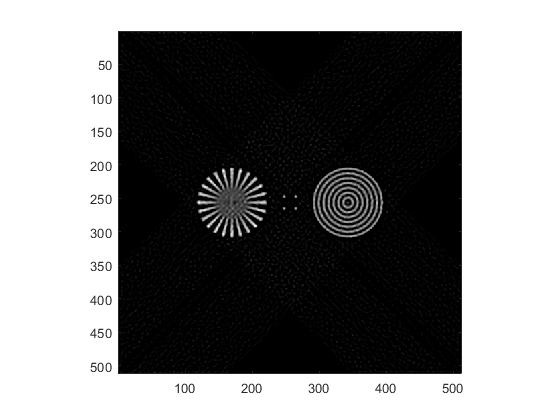

figure; imagesc(recMPIMN3XTv2(:,:,locmXTv2))
axis square
colormap gray

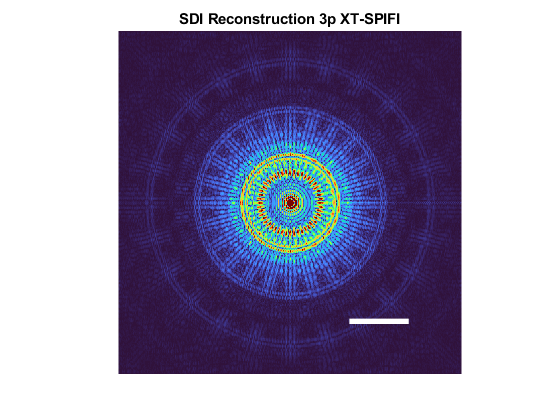

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(recMPIMN3XT(:,:,locmXT))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
colormap Turbo
title('SDI Reconstruction 3p XT-SPIFI','FontWeight',"bold")
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDI3pSPIFIwithNoiseSpatFreq.svg')

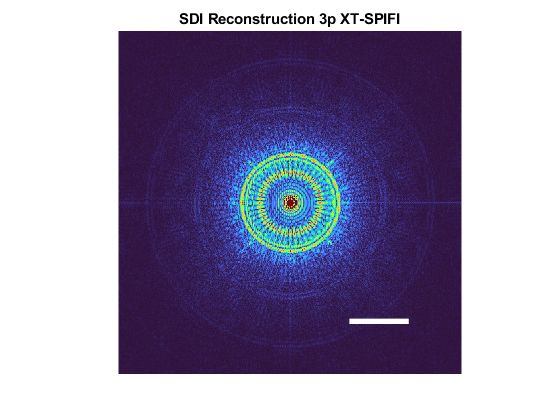

figure; imagesc(fx,fx,Norm(abs(fftshift(fft2(recMPIMN3XTv2(:,:,locmXTv2))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
colormap Turbo
title('SDI Reconstruction 3p XT-SPIFI','FontWeight',"bold")
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDI3pXTSPIFIwithNoiseSpatFreq.svg')

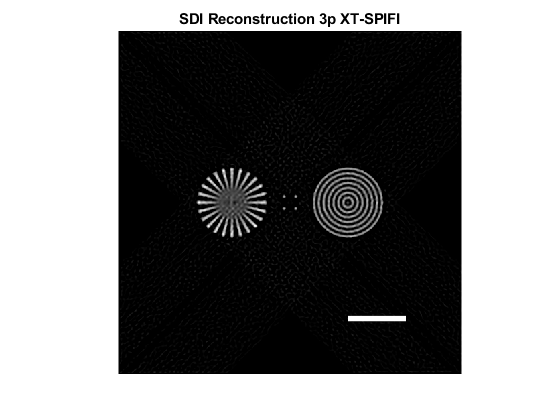

figure;
imagesc(x,x,recMPIMN3XTv2(:,:,locmXTv2))
colormap gray
axis square
axis off
title('SDI Reconstruction 3p XT-SPIFI','FontWeight',"bold")
hold on
line([5 10],[10 10],'Color','white','LineWidth',4)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrec3pXTSPIFIwNoise.svg')

Ntheta=20;
%trueimFave=GabeRadialAvg(abs(fftshift(fft2(trueimage))),Ntheta);
FaveRGNXT3=GabeRadialAvg(abs(fftshift(fft2(recMPIMN3XTv2(:,:,locmXTv2)))),Ntheta);
%FaveRGN2=GabeRadialAvg(abs(fftshift(fft2(RGN2))),Ntheta);
% FaveGN3=GabeRadialAvg(abs(fftshift(fft2(GN3))),Ntheta);
% FaveGN2=GabeRadialAvg(abs(fftshift(fft2(GN2))),Ntheta);
% FaveNF3=GabeRadialAvg(abs(fftshift(fft2(NF3))),Ntheta);
% FaveNF2=GabeRadialAvg(abs(fftshift(fft2(NF2))),Ntheta);

FaveGN3H1XT=GabeRadialAvg(abs(fftshift(fft2(imNGXT3v3cN(:,:,1)))),Ntheta);
FaveGN3H2XT=GabeRadialAvg(abs(fftshift(fft2(imNGXT3v3cN(:,:,2)))),Ntheta);
FaveGN3H3XT=GabeRadialAvg(abs(fftshift(fft2(imNGXT3v3cN(:,:,3)))),Ntheta);
FaveGN3H4XT=GabeRadialAvg(abs(fftshift(fft2(imNGXT3v3cN(:,:,4)))),Ntheta);
FaveGN3H5XT=GabeRadialAvg(abs(fftshift(fft2(imNGXT3v3cN(:,:,5)))),Ntheta);
FaveGN3H6XT=GabeRadialAvg(abs(fftshift(fft2(imNGXT3v3cN(:,:,6)))),Ntheta);


% FaveGN2H1=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,1)))),Ntheta);
% FaveGN2H2=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,2)))),Ntheta);
% FaveGN2H3=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,3)))),Ntheta);
% FaveGN2H4=GabeRadialAvg(abs(fftshift(fft2(imgN2new1N(:,:,4)))),Ntheta);

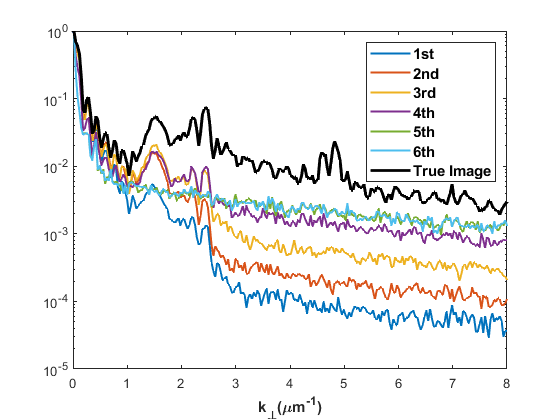

figure; semilogy(fx,(Norm(FaveGN3H1XT)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


semilogy(fx,(Norm(FaveGN3H2XT)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H3XT)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H4XT)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H5XT)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveGN3H6XT)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('k_{\perp}(\mum^{-1})','FontWeight','Bold')
legend({'1st','2nd','3rd','4th','5th','6th','True Image'},'FontWeight','Bold','FontSize',11)
% semilogy((Norm(FaveN3H5(end/2:end))))
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pSPIFIN_radialave_spat_freq.svg')

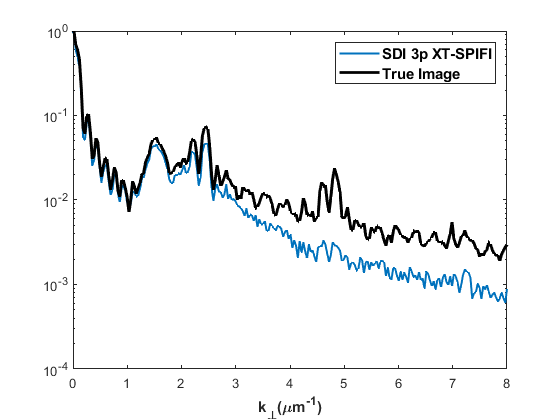

figure; semilogy(fx,(Norm(FaveRGNXT3)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


% semilogy(fx,(Norm(FaveGN3H2)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H3)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H4)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H5)),'LineWidth',1.5)
% semilogy(fx,(Norm(FaveGN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('k_{\perp}(\mum^{-1})','FontWeight','Bold')
legend({'SDI 3p XT-SPIFI','True Image'},'FontWeight','Bold','FontSize',11)
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrec3pXTSPIFIN_radialave_spat_freq.svg')

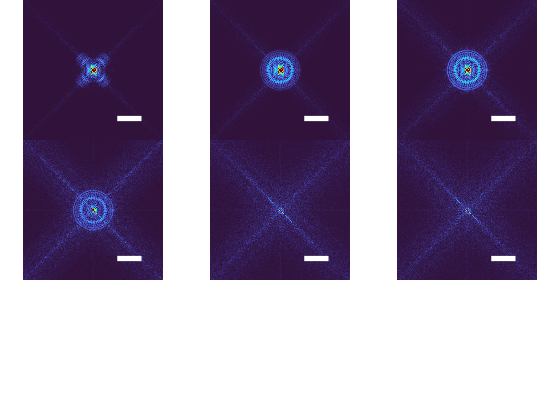

figure;

tiledlayout(3,3,"TileSpacing","none","Padding","tight");
colormap Turbo
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imNGXT3v3cN(:,:,1))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imNGXT3v3cN(:,:,2))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imNGXT3v3cN(:,:,3))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imNGXT3v3cN(:,:,4))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imNGXT3v3cN(:,:,5))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
nexttile
imagesc(fx,fx,Norm(abs(fftshift(fft2(imNGXT3v3cN(:,:,6))))))
hold on
line([3 6],[6 6],'Color','white','LineWidth',4)
caxis([0 .05])
axis square
axis off
saveas(gcf,'SDI_MPSPIFI_SDIPaper/3pXTSPIFINspat_freq.svg')


for ii=1:size(imNGXT3v3cN,3)
    errorharmsimgNXT3(ii)=immse(Norm(imNGXT3v3cN(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imNG3v3N,3)
    errorharmsimimgN3(ii)=immse(Norm(imNG3v3N(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
% for ii=1:size(imgNFXT3,3)
%     errorharmsimgNFXT3sm(ii)=ssim(Norm(imgNFXT3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
%     
% end
% for ii=1:size(imgNF3,3)
%     errorharmsimimgNF3sm(ii)=ssim(Norm(imgNF3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
%     
% end
% for ii=1:size(imgN2new1N,3)
%     errorharmsRGN2(ii)=immse(Norm(imgN2new1N(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
%     
% end
% figure; plot(errorharmsGNXT3)
% hold on
% plot(errorharmsimNG3v2)

figure; plot(errorharmsimgNFXT3)
hold on
plot(errorharmsimimgNF3)

% figure; plot(errorharmsimgNFXT3sm)
% hold on
% plot(errorharmsimimgNF3sm)
% figure; plot(errorharmsRGN2)
% % Corresponding error in reconstructions
% eval
% eval2

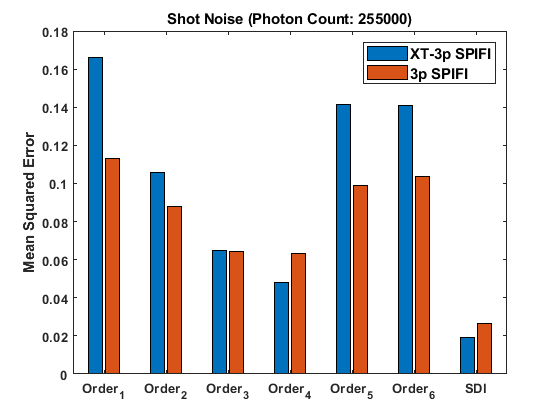

Xn = categorical({'Order_1','Order_2','Order_3','Order_4','Order_5','Order_6','SDI'});

Yn = [errorharmsimgNXT3(1) errorharmsimimgN3(1); errorharmsimgNXT3(2) errorharmsimimgN3(2); errorharmsimgNXT3(3) errorharmsimimgN3(3); errorharmsimgNXT3(4) errorharmsimimgN3(4); errorharmsimgNXT3(5) errorharmsimimgN3(5); errorharmsimgNXT3(6) errorharmsimimgN3(6); evalXTv2 eval;];
figure;
bar(Xn,Yn)
ylabel('Mean Squared Error','FontWeight',"bold")
title('Shot Noise (Photon Count: 255000)','FontWeight',"bold")
legend({'XT-3p SPIFI','3p SPIFI'},'FontWeight',"bold",'FontSize',11)
set(gca,'FontWeight',"bold")
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrecN3p_MSEbargraph_SPIFIvsXT.svg')

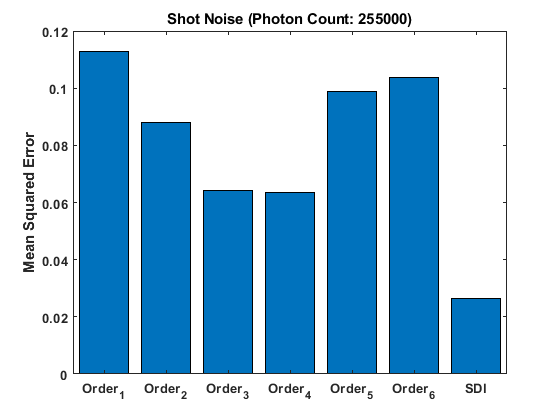

Xn = categorical({'Order_1','Order_2','Order_3','Order_4','Order_5','Order_6','SDI'});

Yn = [errorharmsimimgN3(1); errorharmsimimgN3(2); errorharmsimimgN3(3); errorharmsimimgN3(4); errorharmsimimgN3(5); errorharmsimimgN3(6); eval;];
figure;
bar(Xn,Yn)
ylabel('Mean Squared Error','FontWeight',"bold")
title('Shot Noise (Photon Count: 255000)','FontWeight',"bold")
%legend({'XT-3p SPIFI','3p SPIFI'},'FontWeight',"bold",'FontSize',11)
set(gca,'FontWeight',"bold")
saveas(gcf,'SDI_MPSPIFI_SDIPaper/SDIrecN3p_MSEbargraph_SPIFI.svg')